# Rise Time of Underdamped Second Order System Step Response

According to the Nise textbook (7th Ed.) "a precise analytical relationship between rise time and damping ratio cannote be found."  Instead a numerical solution is provided as represented by Nise FIGURE 4.16

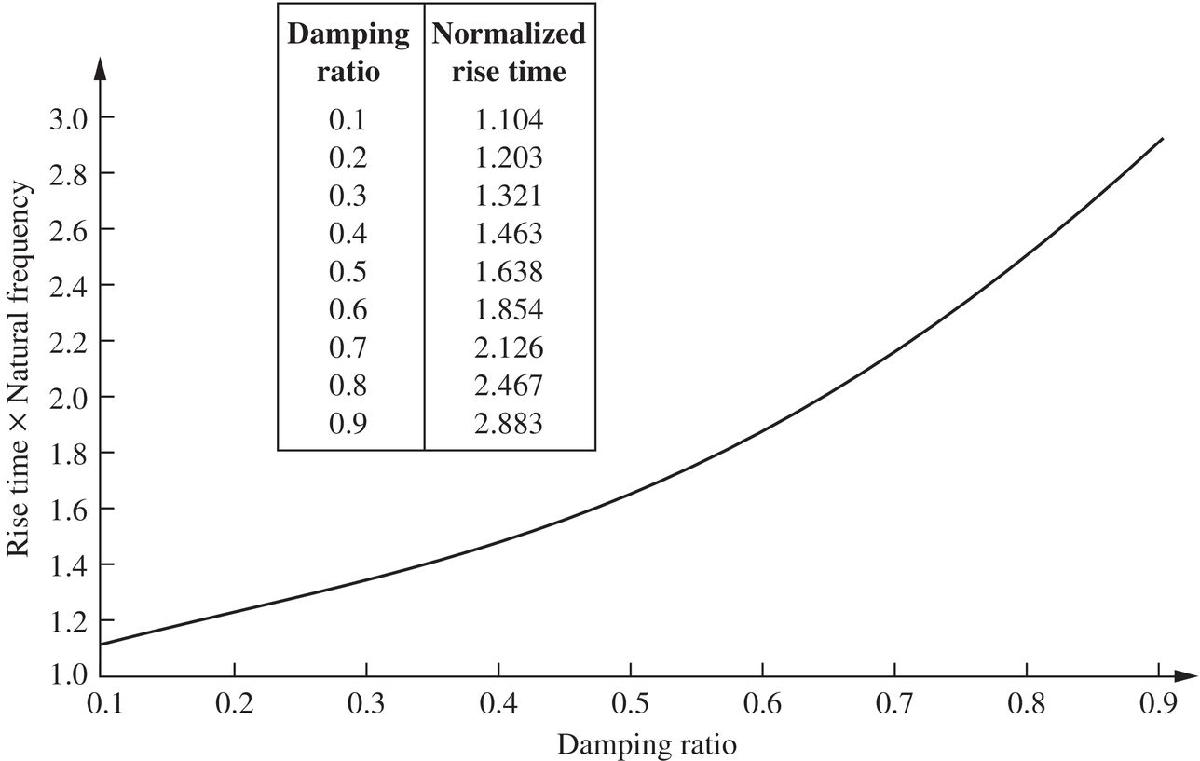

and the following footnote:

  Figure 4.16 can be approximated by the following polynomials

$\omega_n T_r = 1.76 \zeta^3 - 0.417 \zeta ^2 +1.039 \zeta +1$  (max. error less than 1/2% for $0<\zeta<0.9$

## Graph the data and Nise polynomial

Data from FIGURE 4.16

zetas = linspace(0.1, 0.9, 9);
nrts = [1.104, 1.203, 1.321, 1.464, 1.638, 1.854, 2.126, 2.467, 2.883];

Evaluage the given polynomial at the same values of $\zeta.$

nisep = [1.76, -0.417, 1.039, 1];
z = linspace(0, 1.0, 100);
nisevals = polyval(nisep, z);

Graph

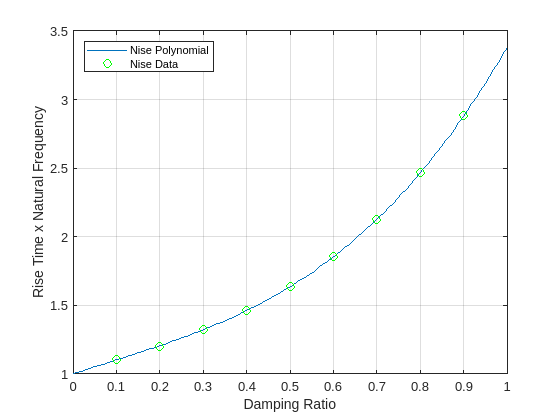

figure; 
clf();
plot(z, nisevals)
hold on
plot(zetas, nrts, 'go')
xlabel('Damping Ratio')
ylabel('Rise Time x Natural Frequency')
grid on
legend('Nise Polynomial','Nise Data','location','northwest')

## Reproducing the polynomial

We can use the data in the table to fit our own third order polynomial

mypoly = polyfit(zetas, nrts, 3)

mypoly =     1.7534   -0.4023    1.0318    1.0015


We find that the values are slightly different.

Overlay on the original graph to qualitatively compare.

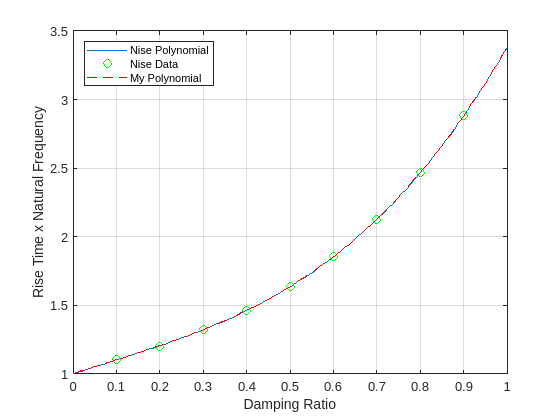

plot(z, polyval(mypoly, z), 'r--')
legend('Nise Polynomial','Nise Data','My Polynomial','location','northwest')

Compare quantitatively using the root-mean-square of the normalized error

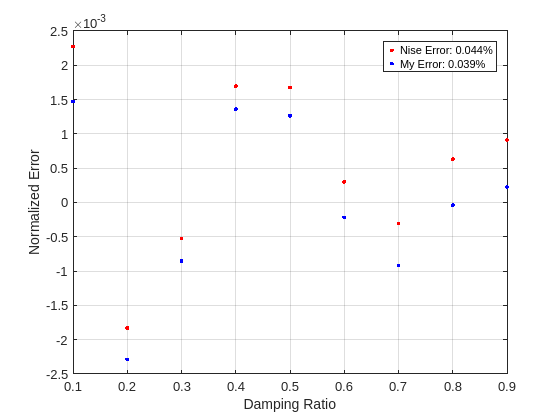


niseerr = (nrts - polyval(nisep, zetas))./nrts;
myerr = (nrts - polyval(mypoly, zetas))./nrts;
figure(2); clf();
plot(zetas, niseerr,'r.')
hold on;
plot(zetas, myerr,'b.')
grid on
legend(sprintf('Nise Error: %.3f%%',100*sqrt(sum(niseerr.^2))/length(niseerr)), ...
    sprintf('My Error: %.3f%%',100*sqrt(sum(myerr.^2))/length(myerr)))
xlabel('Damping Ratio')
ylabel('Normalized Error')

#### It appears that our polynimial has generates a more accurate estimate of the Nise data than the Nise polynomial!  But the differences are not significant.

This suggests that the data points used to generate the Nise polynomial are not the same as the ones listed in Figure.  Perhaps they used a denser sampling?